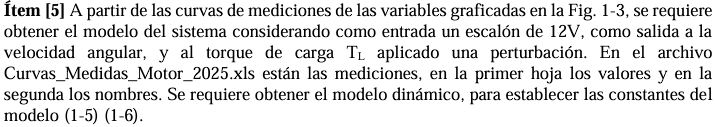

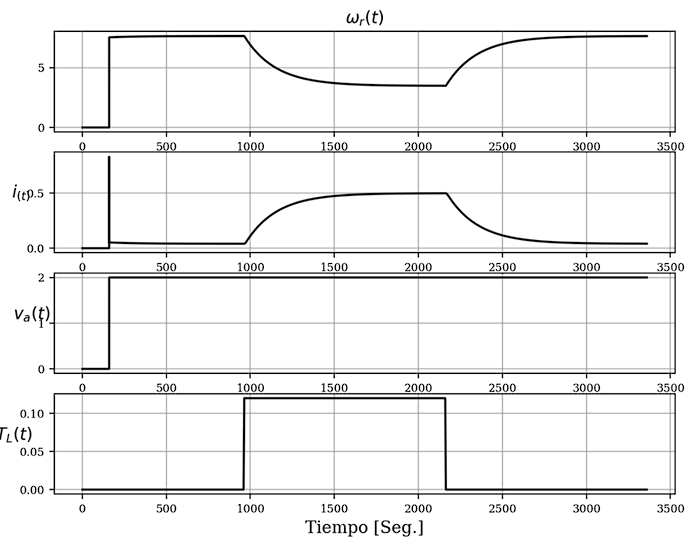

Lectura de datos :  

clear all; clc; close all;

opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Hoja1";
opts.DataRange = "A2:E1500";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\Maca\Documents\UNC\4toAÑO\1CUATRI\SC2\Folder Github TP´s\Control-System-II-TP-s\TP1\documentation\Curvas_Medidas_Motor_2025_v.xls", opts, "UseExcel", false);

t = tbl.VarName1;
Wr = tbl.VarName2;
Ia= tbl.VarName3;
Va= tbl.VarName4;
Tq = tbl.VarName5;
clear opts tbl

Gráficas: 

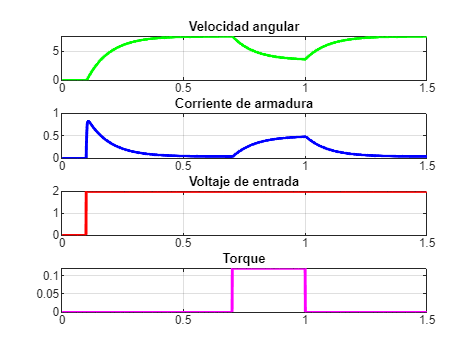

figure; % Creación de la figura sin especificar un número, MATLAB asignará automáticamente
hold on

subplot(4,1,1);
plot(t, Wr, 'g', 'LineWidth', 2);
title('Velocidad angular');
grid on;

subplot(4,1,2);
plot(t, Ia, 'b', 'LineWidth', 2);
title('Corriente de armadura');
grid on;

subplot(4,1,3);
plot(t, Va, 'r', 'LineWidth', 2);
title('Voltaje de entrada'); 
grid on;

subplot(4,1,4);
plot(t,Tq, 'm', 'LineWidth', 2);
title('Torque'); 
grid on;
hold off

Aplico Chen para encontrar Wr/Va

% Apply The Second-Order Systems with differents poles method 

% y(t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(t1/T1))- (((T3-T2)/(T1-T2))*exp(-t1/T2)));
% y(2*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(2*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(2*t1)/T2)));
% y(3*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(3*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(3*t1)/T2)));

% Obtain maximium value from t (RLC circuit measure).
max_t= max(t);

% Define step amplitude.
A= 2;

% Take time and voltage arrays
% Time array.
t0= t;
%Vc array.
y=Wr;

%Implementación de Método de CHen para G(s)=Wr/Va
% Take three point to apply Chen Method.

%i=155;
i=155;
t_inic= t0(i);
% Define step.
%h= 62;
h=62;
% Obtain y1.
t_t1= t0(i)

t_t1 = 0.1560

y_t1ab= y(i)

y_t1ab = 3.3075

y_t1= y(i)/A

y_t1 = 1.6537

% Obtain y2.
t_2t1= t0(i+h)

t_2t1 = 0.2180

y_2t1ab= y(i+h)

y_2t1ab = 5.4228

y_2t1= y(i+h)/A

y_2t1 = 2.7114

% Obtain y3.
t_3t1= t0(i+(2*h))

t_3t1 = 0.2800

y_3t1ab= y(i+(2*h))

y_3t1ab = 6.5045

y_3t1= y(i+(2*h))/A

y_3t1 = 3.2523

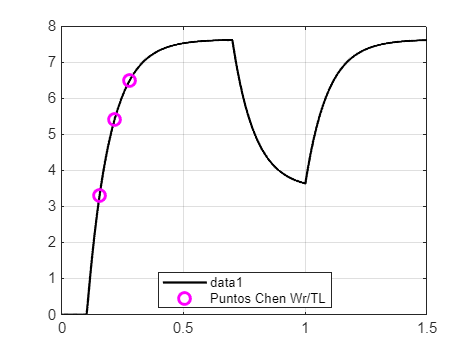

%Ploteo de puntos seleccionados 
figure;
plot(t, Wr, 'k-', 'LineWidth', 1.5); 
hold on;
grid on;
plot([t_t1, t_2t1, t_3t1], [y_t1ab, y_2t1ab, y_3t1ab], 'mo', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Puntos Chen Wr/TL');
legend('show', 'Location', 'best');
hold off; legend('show', 'Location', 'best');

disp(['Puntos Chen (t): ', num2str([t_t1, t_2t1, t_3t1])]);

Puntos Chen (t): 0.156       0.218        0.28


disp(['Puntos Chen (Wr abs): ', num2str([y_t1ab, y_2t1ab, y_3t1ab])]);

Puntos Chen (Wr abs): 3.3075      5.4228      6.5045




% Normalize gain
% Add abs(y(end)), because 'end' take value= -12V (Alternate input signal).
K= abs(y(end))/(A)

K = 3.8093


% Calculating k1, k2, k3.
k1= ((y_t1)/K)-1;
k2= ((y_2t1)/K)-1;
k3= ((y_3t1)/K)-1;

% Calculating b, alfa1, alfa2.
b= 4*(k1^(3))*k3- 3*(k1^2)*(k2^2)- 4*(k2^3)+ (k3^2)+ 6*k1*k2*k3;
alfa1= (k1*k2+ k3- sqrt(b))/(2*((k1^2)+ k2));
alfa2= (k1*k2+ k3+ sqrt(b))/(2*((k1^2)+ k2));

% Calculating Beta.
% beta= (2*(k1^3)+ 3*k1*k2+ k3- sqrt(b))/(sqrt(b));
% Alternative
beta= (k1+alfa2)/(alfa1-alfa2);


% Calculo las ctes de tiempo T1, T2 y T3.
% A t_t1 le resto 0.1 seg. del retardo
desp=0.1

desp = 0.1000

T1= -(t_t1-desp)/(log(alfa1))

T1 = 0.0143

T2= -(t_t1-desp)/(log(alfa2))

T2 = 0.0825

T3= beta *(T1- T2)+ T1

T3 = 0.0061


% Build Transfer Function
s= tf('s');
sys= K/((T1*s+1)*(T2*s+1)); %%sin retardo
sys1= exp(-s*desp)*sys


sys1 =
 
                           3.809
  exp(-0.1*s) * ---------------------------
                0.001179 s^2 + 0.0968 s + 1
 
Continuous-time transfer function.
Model Properties


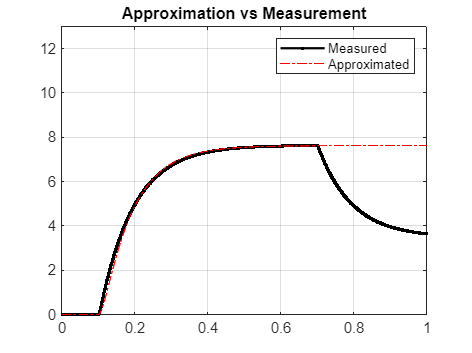

% [num, den]= tfdata(sys, 'v');

% Plot approximated step response
% Obtain step response with delay.
% [ys, ts]= step(sys*exp(-s*0.01), 'r-', 0.16);
figure;
[ys, ts]= step(A*sys1, 'r-', 1.5);   %aproximada
plot(t, Wr, 'k.-','LineWidth',1.5); %medida 
hold on;
plot(ts, ys, 'r-.');%aproximada
xlim([0, 1]);
ylim([0, 13]);
legend('Measured', 'Approximated');
title('Approximation vs Measurement');
grid on;

Aplico Chen para encontrar Wr/TL

disp('--- Wr/TL ---');

--- Wr/TL ---



% Obtener Valores Estacionarios de gráficas
w_001 = 7.6186; % Velocidad Wr ANTES de aplicar Tq (aprox. t=0.5-0.7s)
w_002 = 3.64152; % Velocidad Wr DESPUÉS de aplicar Tq (aprox. t=1.2-1.5s)
% Amplitud del escalón de Torque 
TL_amp = 0.12; 
disp(['Amplitud escalón Torque (TL_amp): ', num2str(TL_amp)]);

Amplitud escalón Torque (TL_amp): 0.12



% --- 2) Cálculo de Ganancia Estática k_tl ---
% Ganancia para las fórmulas de Chen (positiva: caída de velocidad / aumento de torque)
k_tl = (w_001 - w_002) / TL_amp;
% Ganancia física real (negativa)
k_tl_fisica = (w_002 - w_001) / TL_amp;

% Selección de Puntos para Chen (Durante el transitorio de Torque) ---
% Tiempo estimado en que inicia el escalón de Torque 
ret = 0.7;
disp(['Inicio estimado del escalón de Torque (ret): ', num2str(ret)]);

Inicio estimado del escalón de Torque (ret): 0.7


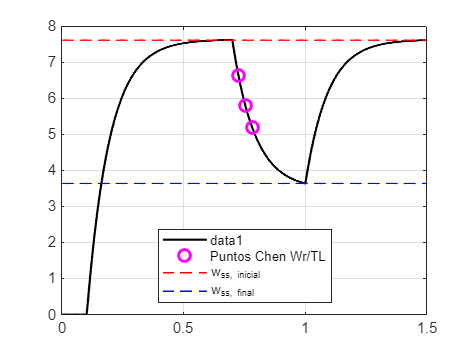


%valores de referencia:
ii = 725; % Índice inicial
ht = 28;  % Incremento índice

% Obtener tiempos y valores ABSOLUTOS de Wr en esos puntos
t1w = t(ii);
y1w_abs = Wr(ii); % ¡Valor absoluto de Wr, NO dividir por TL_amp!
t2w = t(ii+ht);
y2w_abs = Wr(ii+ht);
t3w = t(ii+2*ht);
y3w_abs = Wr(ii+2*ht);

% Graficar los puntos seleccionados para verificar
figure;
plot(t, Wr, 'k-', 'LineWidth', 1.5); 
hold on;
grid on;
plot([t1w, t2w, t3w], [y1w_abs, y2w_abs, y3w_abs], 'mo', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Puntos Chen Wr/TL');
plot(t, ones(size(t))*w_001, 'r--', 'LineWidth', 1, 'DisplayName', 'w_{ss, inicial}');
plot(t, ones(size(t))*w_002, 'b--', 'LineWidth', 1, 'DisplayName', 'w_{ss, final}');
legend('show', 'Location', 'best');
hold off; legend('show', 'Location', 'best');

disp(['Puntos Chen (t): ', num2str([t1w, t2w, t3w])]);

Puntos Chen (t): 0.726       0.754       0.782


disp(['Puntos Chen (Wr abs): ', num2str([y1w_abs, y2w_abs, y3w_abs])]);

Puntos Chen (Wr abs): 6.644      5.8162      5.2048



% --- 4) Normalización para Chen (Calcular la "caída de velocidad" yid) ---
% Calcula la desviación respecto al estado estacionario INICIAL y la niega
yid_1 = -(y1w_abs - w_001); % Caída de velocidad en t1w (valor positivo)
yid_2 = -(y2w_abs - w_001); % Caída de velocidad en t2w (valor positivo)
yid_3 = -(y3w_abs - w_001); % Caída de velocidad en t3w (valor positivo)
disp(['Valores yid (caída velocidad): ', num2str([yid_1, yid_2, yid_3])]);

Valores yid (caída velocidad): 0.9746      1.8024      2.4138





% --- 5) Aplicación del método de Chen ---
% A) Calcular k1w, k2w, k3w
% k_i = y_efectivo / K_efectiva - 1
% y_efectivo = yid_x
% K_efectiva = caída total de velocidad = w_001 - w_002 = k_tl * TL_amp
K_efectiva = k_tl * TL_amp;
k1w = yid_1 / K_efectiva - 1;
k2w = yid_2 / K_efectiva - 1;
k3w = yid_3 / K_efectiva - 1;
disp(['Valores k_chen (k1w, k2w, k3w): ', num2str([k1w, k2w, k3w])]);

Valores k_chen (k1w, k2w, k3w): -0.75495    -0.54681    -0.39307


% Verifica que k1w, k2w, k3w sean negativos

% B) Calcular alfa1w, alfa2w, betaw
bwr = 4*(k1w^3)*k3w - 3*(k1w^2)*(k2w^2) - 4*(k2w^3) + (k3w^2) + 6*k1w*k2w*k3w;
den_alfa = 2*(k1w^2 + k2w);
alfa1w = (k1w*k2w + k3w - sqrt(bwr)) / den_alfa; % Chen ec.21
alfa2w = (k1w*k2w + k3w + sqrt(bwr)) / den_alfa; % Chen ec.22
den_beta = alfa1w - alfa2w;
betaw = (k1w + alfa2w) / den_beta; % Chen ec.23

disp(['Alfa1w, Alfa2w, Betaw: ', num2str([alfa1w, alfa2w, betaw])]);

Alfa1w, Alfa2w, Betaw: 0.13622     0.71757    0.064299


% Verifica que alfa1w y alfa2w sean reales y entre 0 y 1

% C) Calcular las constantes de tiempo T1w, T2w, T3w
% ¡IMPORTANTE! Usar el tiempo TRANSCURRIDO desde el inicio del escalón 'ret'
t_rel_1 = t1w - ret; % Tiempo relativo del primer punto Chen
T1w = real(-(t_rel_1) / log(alfa1w)); % Ec. de Chen 25
T2w = real(-(t_rel_1) / log(alfa2w)); % Ec. de Chen 25
T3w = real((betaw * (T1w - T2w)) + T1w); % Ec. de Chen 25

disp(['Constantes de tiempo T1w, T2w, T3w: ', num2str([T1w, T2w, T3w])]);

Constantes de tiempo T1w, T2w, T3w: 0.013042    0.078339   0.0088438



% --- 6) Definición de la Función de Transferencia Gw = Wr(s)/TL(s) ---
s = tf('s');

Gw = tf(k_tl_fisica * [T3w, 1], conv([T1w, 1], [T2w, 1]));

% Gw = Gw * exp(-s*(retardo_adicional_si_existe));
disp('Función de Transferencia Wr(s)/TL(s) [Gw]:');

Función de Transferencia Wr(s)/TL(s) [Gw]:


Gw


Gw =
 
       -0.2931 s - 33.14
  ----------------------------
  0.001022 s^2 + 0.09138 s + 1
 
Continuous-time transfer function.
Model Properties


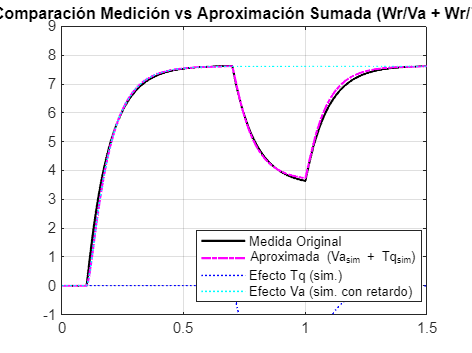


% --- 7) Gráfica de Comparación ---
% Simular el efecto del TORQUE usando la FT obtenida (Gw)
[y_Gw, t_Gw] = lsim(Gw, Tq, t); % Simula Wr_debido_a_Tq = Gw * Tq

% [y_Gv, t_Gv] = lsim(sys1, Va, t); % Simula Wr_debido_a_Va = sys1 * Va
% OJO: lsim aplica toda la señal Va, no solo un escalón. Si sys1 se obtuvo
% solo para el escalón inicial, esto podría no ser perfecto.
% Una mejor aproximación es usar la ganancia K y los polos/ceros de sys:
[y_Gv, t_Gv] = lsim(sys, Va, t); % Usa sys (sin retardo explícito)


figure;
plot(t, Wr, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Medida Original'); % Medida original
hold on;
% Sumar las respuestas simuladas: Wr_total_sim = Efecto_Va + Efecto_Tq
plot(t, y_Gv + y_Gw, 'm-.', 'LineWidth', 1.5, 'DisplayName', 'Aproximada (Va_{sim} + Tq_{sim})'); % Suma de simulaciones lsim
plot(t_Gw, y_Gw, 'b:', 'LineWidth', 1, 'DisplayName', 'Efecto Tq (sim.)'); % Efecto sólo del Torque (simulado)
plot(t, y_Gv, 'c:', 'LineWidth', 1, 'DisplayName', 'Efecto Va (sim. con retardo)'); % Efecto sólo del Voltaje (simulado)

xlim([0, 1.5]);
ylim([-1, 9]);   
legend('show', 'Location', 'best');
title('Comparación Medición vs Aproximación Sumada (Wr/Va + Wr/Tq)');
grid on;
hold off;

Cálculo de los parámetros del Motor

 
%Comienzo calculando la resistencia a partir de la Imax (en el arranque) y la tension de 2V
[Imax,indm]= max(Ia)

Imax = 0.8287

indm = 109

Va_Imax=Va(109)

Va_Imax = 2

Ra= Va_Imax/Imax % Va/Imax

Ra = 2.4136


% fórmulas propuestas por el profe en el Colab

K1_Chen= K;
K2_Chen= k_tl_fisica;

Bm=0

Bm = 0

La= (Ra*T1*T2)/(T1+T2)

La = 0.0294

Ki= (K1_Chen * Ra)/ (K2_Chen);
Jm= (T1+T2)/ K2_Chen;
Km= 1/ K1_Chen

Km = 0.2625

 if Ki<0 || Jm<0 
     Ki=0
     Jm=0
 end

Ki = 0

Jm = 0

Simulación del funcionamiento del motor a partir de los parámetros calculados

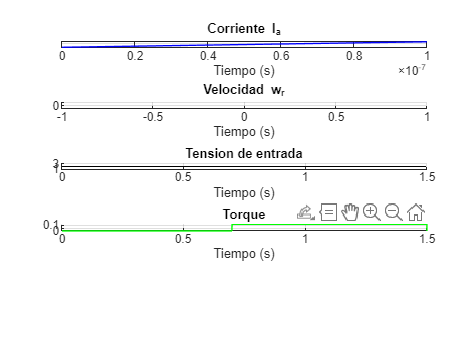

% Modelado en  espacio de estados

A = [-Ra/La -Km/La 0 ; Ki/Jm -Bm/Jm 0 ; 0 1 0];  % matriz de estados
B = [1/La 0 ; 0 -1/Jm ; 0 0];                % matriz de entrada 
C = [0 1 0] ;                              % matriz de salida                                                       
D = [0 0];                                % matriz de transmisión directa 


% INICIALIZACIÓN DE ESTADOS
Xop      = [0 0 0]';                
wr(1)    = 0;
ia(1)    = 0;
theta(1) = 0;
x = [ia(1) wr(1) theta(1)]';

%Simulacion
dt = 1e-7; % Paso para la integracion
tsim = 1.5; % Tiempo total de simulacion
tt= 0: dt: tsim; % Vector tiempo

%Genero la señal de entrada 
Va_sim  = 2 * ones(1, length(tt)); 

%Genero un vector torque para poder usarlo como entrada y graficas

TL = zeros(1, length(tt));
for ii=1:tsim/dt
    varr = tt(ii);
    if (varr>=0.7 && varr<=1.5)
        TL(ii) = 0.12;
    else
        TL(ii) = 0;
    end
end


% EULER
for ii=1:(length(tt)-1)
    % Cálculo de las derivadas
    xp = A*(x - Xop)+B* [Va_sim(ii) TL(ii)]';
    x = x + xp * dt;
    wr(ii+1) = C*x;
    ia(ii+1) = x(1);
    theta(ii+1) = x(3);
end


% GRÁFICAS

figure(4);
% Corriente (Ia)
subplot(5,1,1)
plot(tt, ia, 'b')
xlabel('Tiempo (s)'); ylabel('Corriente i_a (A)')
title('Corriente I_a');
grid on;

% Velocidad angular
subplot(5,1,2);hold on;
plot(tt, wr, 'r');
xlabel('Tiempo (s)'); ylabel('Velocidad \omega_r (rad/s)');
title('Velocidad w_r');
grid on;

% Tensión, Va
subplot(5,1,3);hold on;
plot(tt,Va_sim,'k');
xlabel('Tiempo (s)'); ylabel('Tension (V)');
title('Tension de entrada');
grid on;

%Torque
subplot(5,1,4);hold on;
plot(tt,TL,'g');
xlabel('Tiempo (s)'); ylabel('Torque, [N.m]');
title('Torque');
grid on;